**LABORATORIO TRANSFORMADA DE LA-PLACE**

**grupo 6 equipo 6**

**Diseño 1:**

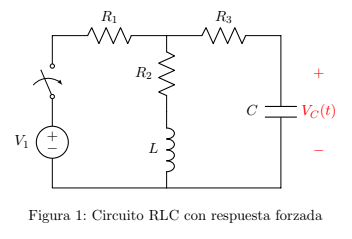

Escogemos los valores de los elementos

clc, clear, close all
format short g

vf = 5; %[V]dc

r1 = 100; %[ohms]
r2 = 220; %[ohms]
r3 = 50; %[ohms]

l = 9e-3; %[H]
c = 1e-6; %[F]


pasamos todo al dominio de s

syms s t i1 i2

v1 = vf/s

$$v1 = \frac{5}{s}$$

z1 = r1;
z2 = r2;
z3 = r3;
zl = l*s

$$zl = \frac{9\,s}{1000}$$

zc = 1/(s*c)

$$zc = \frac{1000000}{s}$$

Para t<0 tenemos el circuito no energizado por lo tanto no vamos a tener condiciones iniciales, y porcedemos a analizar directamente el circuito en t>0.

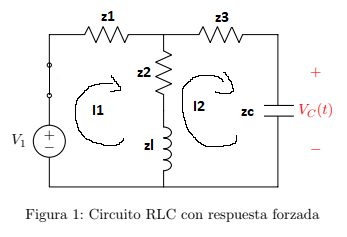

planteamos las ecuaciones de malla

ec1 = -v1 + z1*i1 + z2*(i1-i2) + zl*(i1-i2) == 0

$$ec1 = 320\,i_{1}-220\,i_{2}+\frac{9\,s\,\left(i_{1}-i_{2}\right)}{1000}-\frac{5}{s}=0$$

ec2 = zl*(i2-i1) + z2*(i2-i1) + z3*i2 + zc*i2 == 0

$$ec2 = 270\,i_{2}-220\,i_{1}-\frac{9\,s\,\left(i_{1}-i_{2}\right)}{1000}+\frac{1000000\,i_{2}}{s}=0$$

resolvemos el sistema de ecuaciones 2x2 reemplazando I1 en la ecuacion 2:

obteniendo la funcion de corriente I2, donde x = I2

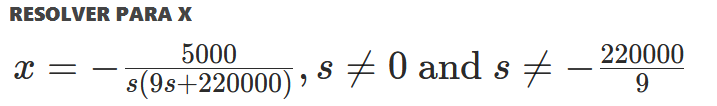

I2 = -5000/(s*(9*s+220000))

$$I2 = -\frac{5000}{s\,\left(9\,s+220000\right)}$$

vc = zc*I2

$$vc = -\frac{5000000000}{s^{2}\,\left(9\,s+220000\right)}$$

vc_t = ilaplace(vc)

$$vc\_t = \frac{225}{242}-\frac{225\,{\mathrm{e}}^{-\frac{220000\,t}{9}}}{242}-\frac{250000\,t}{11}$$

Lo verificamos en el simulador:

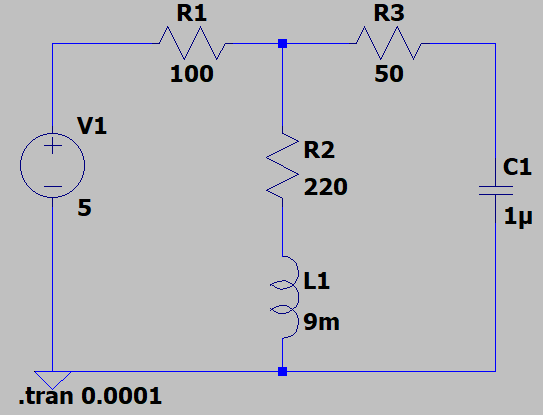

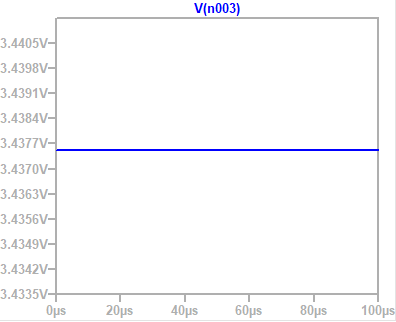

analisis sin tplace

vc= (r2/(r1+r2))*vf

vc =        3.4375


**Diseño 2:**

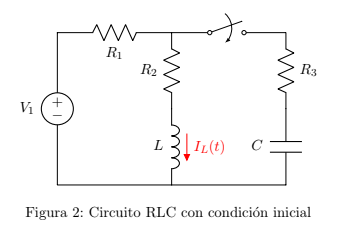

Analisis en t<0

Il = vf/(r1+r2) %[A]

Il =      0.015625
